% mm_traj_tracking_xb_final

% function mm_traj_tracking_xb_final()
%MM_TRAJ_TRACKING_XB_FINAL
%
% Trajectory tracking for the mobile manipulator using the reduced dynamics:
%
%   X = [q; eta_dot]
%   q = [x_b; y_b; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3]
%   eta_dot = [theta_r_dot; theta_l_dot; theta_1_dot; theta_2_dot; theta_3_dot]
%
% We design a kinematically-consistent reference trajectory for the SAME
% coordinates (x_b, y_b) used by the dynamic model (arm base point O_b),
% by integrating q_dot_d = R(q) * eta_dot_d(t).
%
% Then we apply computed-torque / feedback linearization in eta-space:
%
%   M1*eta_ddot + (C1 + D_eta)*eta_dot + G1 = B1*u
%
% and track:
%   x_b(t), y_b(t), theta_m(t), theta_1(t), theta_2(t), theta_3(t).
%
% Control efforts u = [tau_r; tau_l; tau_1; tau_2; tau_3] are logged and
% plotted at the end.

    clc; clearvars; close all;

    % --- logging of control efforts (torques) ---
    global T_LOG U_LOG
    T_LOG = [];        % time stamps
    U_LOG = [];        % torques [tau_r tau_l tau_1 tau_2 tau_3]

    %% Paths
    project_root = './';
    addpath(fullfile(project_root, 'dynamics_library'));
    addpath(fullfile(project_root, 'data'));
    disp('✅ Paths added.');

✅ Paths added.



    %% Load physical parameters
    [phys, ~] = mm_params_build_save_load('load');

Loaded: mm_params.mat


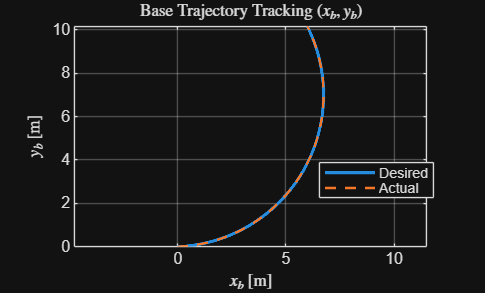


    %% Simulation horizon and reference-grid resolution
    Tf     = 20;        % [s] total time
    dt_ref = 1e-3;      % [s] small step for reference integration

    %% Build kinematically consistent reference trajectory for q_d(t)
    ref = build_reference_trajectory(phys, Tf, dt_ref);

    %% Dimensions
    nq = 8;
    ne = 5;
    nx = nq + ne;

    %% Controller gains in eta-space
    Kp = diag([60 60 50 50 50]);
    Kd = diag([15 15 12 12 12]);    % eta = [theta_r; theta_l; theta_1; theta_2; theta_3]


    %% Initial state: start on the reference trajectory at t = 0
    q0       = ref.q(1, :).';                  % [x_b0; y_b0; theta_m0; ...]
    [eta_dot0, ~] = desired_eta_law(0, phys);  % desired eta_dot at t=0

    X0 = [q0; eta_dot0];
    % size(X0)
    % X0 = ones(13, 1)*0.5;
    %% Control law handle
    u_fun = @(t, q, eta_dot) eta_tracking_controller_ct( ...
        t, q, eta_dot, phys, ref, Kp, Kd);

    %% ODE wrapper
    ode_fun = @(t, X) mm_forward_dynamics_reduced(t, X, u_fun);

    %% Simulate
    tspan = [0 Tf];
    opts  = odeset('RelTol',1e-6, 'AbsTol',1e-8);

    [t, X] = ode45(ode_fun, tspan, X0, opts);

    %% Extract states
    q_hist       = X(:, 1:nq);
    eta_dot_hist = X(:, nq+1:nx); %#ok<NASGU>

    x_b     = q_hist(:,1);
    y_b     = q_hist(:,2);
    theta_m = q_hist(:,3);
    theta1  = q_hist(:,6);
    theta2  = q_hist(:,7);
    theta3  = q_hist(:,8);

    %% Desired trajectory on same time grid
    N = numel(t);
    q_d_hist  = zeros(N, nq);

    for k = 1:N
        [q_dk, ~, ~, ~, ~] = desired_trajectory_from_ref(t(k), phys, ref);
        q_d_hist(k,:) = q_dk.';
    end

    x_b_d     = q_d_hist(:,1);
    y_b_d     = q_d_hist(:,2);
    theta_m_d = q_d_hist(:,3);
    theta1_d  = q_d_hist(:,6);
    theta2_d  = q_d_hist(:,7);
    theta3_d  = q_d_hist(:,8);

    %% =====================  STATE TRACKING PLOTS  =====================

    % (1) Base trajectory (x_b, y_b)
    figure;
    plot(x_b_d, y_b_d, 'LineWidth', 2); hold on;
    plot(x_b,   y_b,   '--', 'LineWidth', 1.5);
    xlabel('$x_b$ [m]','Interpreter','latex');
    ylabel('$y_b$ [m]','Interpreter','latex');
    legend('Desired','Actual','Location','best');
    title('Base Trajectory Tracking $(x_b,y_b)$','Interpreter','latex');
    axis equal; grid on;

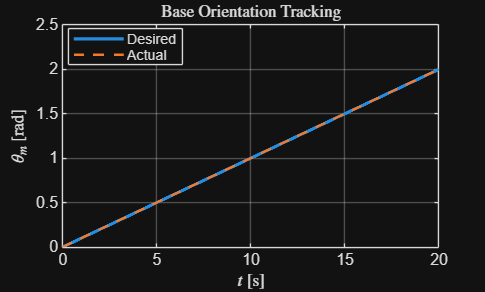


    % (2) Base orientation theta_m
    figure;
    plot(t, theta_m_d, 'LineWidth', 2); hold on;
    plot(t, theta_m,   '--', 'LineWidth', 1.5);
    xlabel('$t$ [s]','Interpreter','latex');
    ylabel('$\theta_m$ [rad]','Interpreter','latex');
    legend('Desired','Actual','Location','best');
    title('Base Orientation Tracking','Interpreter','latex');
    grid on;

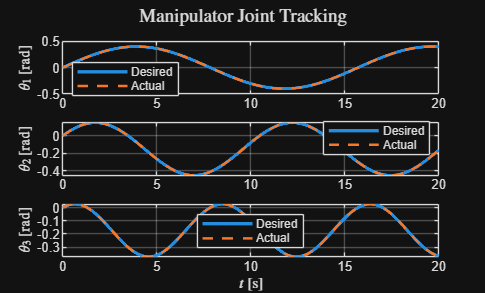


    % (3) Manipulator joint tracking
    figure;
    subplot(3,1,1);
    plot(t, theta1_d, 'LineWidth', 2); hold on;
    plot(t, theta1,   '--', 'LineWidth', 1.5);
    ylabel('$\theta_1$ [rad]','Interpreter','latex');
    legend('Desired','Actual','Location','best');
    grid on;

    subplot(3,1,2);
    plot(t, theta2_d, 'LineWidth', 2); hold on;
    plot(t, theta2,   '--', 'LineWidth', 1.5);
    ylabel('$\theta_2$ [rad]','Interpreter','latex');
    legend('Desired','Actual','Location','best');
    grid on;

    subplot(3,1,3);
    plot(t, theta3_d, 'LineWidth', 2); hold on;
    plot(t, theta3,   '--', 'LineWidth', 1.5);
    xlabel('$t$ [s]','Interpreter','latex');
    ylabel('$\theta_3$ [rad]','Interpreter','latex');
    legend('Desired','Actual','Location','best');
    grid on;

    sgtitle('Manipulator Joint Tracking','Interpreter','latex');

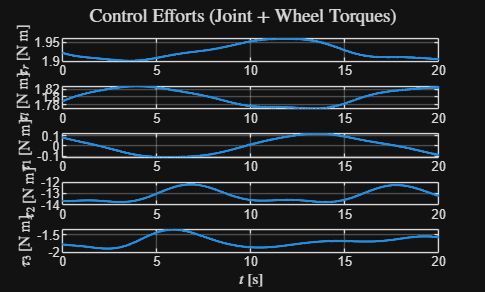


    %% =====================  CONTROL EFFORT PLOTS  =====================
    global T_LOG U_LOG

    % Sort logs by time (ODE45 can call controller in non-monotonic order)
    [T_ctrl, idx] = sort(T_LOG);
    U_ctrl        = U_LOG(idx, :);

    tau_r = U_ctrl(:,1);
    tau_l = U_ctrl(:,2);
    tau_1 = U_ctrl(:,3);
    tau_2 = U_ctrl(:,4);
    tau_3 = U_ctrl(:,5);

    figure;
    subplot(5,1,1);
    plot(T_ctrl, tau_r, 'LineWidth', 1.5);
    ylabel('$\tau_r$ [N m]','Interpreter','latex');
    grid on;

    subplot(5,1,2);
    plot(T_ctrl, tau_l, 'LineWidth', 1.5);
    ylabel('$\tau_l$ [N m]','Interpreter','latex');
    grid on;

    subplot(5,1,3);
    plot(T_ctrl, tau_1, 'LineWidth', 1.5);
    ylabel('$\tau_1$ [N m]','Interpreter','latex');
    grid on;

    subplot(5,1,4);
    plot(T_ctrl, tau_2, 'LineWidth', 1.5);
    ylabel('$\tau_2$ [N m]','Interpreter','latex');
    grid on;

    subplot(5,1,5);
    plot(T_ctrl, tau_3, 'LineWidth', 1.5);
    ylabel('$\tau_3$ [N m]','Interpreter','latex');
    xlabel('$t$ [s]','Interpreter','latex');
    grid on;

    sgtitle('Control Efforts (Joint + Wheel Torques)','Interpreter','latex');


% end

%% =====================================================================
%%  Helper: build reference trajectory q_d(t) using kinematics
%% =====================================================================
function ref = build_reference_trajectory(phys, Tf, dt)
% Integrate q_dot = R(q)*eta_dot_d(t) over [0, Tf] with step dt.
% This gives q_d(t) that is kinematically consistent with R(q).
%
% State layout:
%   q = [x_b; y_b; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3]

    t_vec = 0:dt:Tf;
    N     = numel(t_vec);

    q_ref = zeros(N, 8);   % start from all zeros
    % q_ref = 50*ones(N, 8);  
    for k = 1:N-1
        t  = t_vec(k);
        qk = q_ref(k,:).';

        % desired eta_dot at time t
        [eta_dot_d, ~] = desired_eta_law(t, phys);

        % kinematics q_dot = R(q)*eta_dot
        Rk    = mm_R_fun(qk);      % [8x5]
        qdotk = Rk * eta_dot_d;    % [8x1]

        % Euler integration
        q_ref(k+1,:) = (qk + dt*qdotk).';
    end

    ref.t = t_vec;
    ref.q = q_ref;
end

%% =====================================================================
%%  Helper: analytic desired eta_dot and eta_ddot (wheel + joints)
%% =====================================================================
function [eta_dot_d, eta_ddot_d] = desired_eta_law(t, phys)
% Desired laws for eta_dot and eta_ddot:
%   eta     = [theta_r; theta_l; theta_1; theta_2; theta_3]
%   eta_dot = [theta_r_dot; theta_l_dot; theta_1_dot; theta_2_dot; theta_3_dot]

    r = phys.r;
    L = phys.L;

    % ------- base motion via wheel speeds -------
    % Choose desired "unicycle" v0, w0 and convert to wheel rates.
    v0 = 0.7;      % forward speed [m/s]
    w0 = 0.1;      % yaw rate [rad/s]

    omega_r = (v0 + L*w0) / r;   % right wheel angular speed [rad/s]
    omega_l = (v0 - L*w0) / r;   % left  wheel angular speed [rad/s]

    theta_r_dot_d  = omega_r;
    theta_l_dot_d  = omega_l;
    theta_r_ddot_d = 0;
    theta_l_ddot_d = 0;

    % ------- manipulator joints: sinusoids -------
    % theta_1
    A1 = 0.4;  w1 = 0.4;
    theta1_dot_d  = A1 * w1 * cos(w1*t);
    theta1_ddot_d = -A1 * w1^2 * sin(w1*t);

    % theta_2
    A2 = 0.3;  w2 = 0.6;  phi2 = pi/6;
    theta2_dot_d  = A2 * w2 * cos(w2*t + phi2);
    theta2_ddot_d = -A2 * w2^2 * sin(w2*t + phi2);

    % theta_3
    A3 = 0.2;  w3 = 0.8;  phi3 = pi/3;
    theta3_dot_d  = A3 * w3 * cos(w3*t + phi3);
    theta3_ddot_d = -A3 * w3^2 * sin(w3*t + phi3);

    eta_dot_d = [theta_r_dot_d;
                 theta_l_dot_d;
                 theta1_dot_d;
                 theta2_dot_d;
                 theta3_dot_d];

    eta_ddot_d = [theta_r_ddot_d;
                  theta_l_ddot_d;
                  theta1_ddot_d;
                  theta2_ddot_d;
                  theta3_ddot_d];
end

%% =====================================================================
%%  Helper: get desired trajectory at arbitrary time t from reference
%% =====================================================================
function [q_d, qd_d, eta_d, eta_dot_d, eta_ddot_d] = ...
    desired_trajectory_from_ref(t, phys, ref)
% Interpolate q_d from the precomputed reference, then compute qdot_d
% using the same desired eta_dot law.

    % interpolate q_d (x_b, y_b, theta_m, theta_r, theta_l, theta_1..3)
    q_d = interp1(ref.t, ref.q, t, 'pchip').';

    % desired eta_dot, eta_ddot from analytic law
    [eta_dot_d, eta_ddot_d] = desired_eta_law(t, phys);

    % eta_d is the actuated coordinates of q_d
    eta_d = q_d(4:8);

    % q_dot_d from kinematics at q_d
    R_d   = mm_R_fun(q_d);
    qd_d  = R_d * eta_dot_d;
end

%% =====================================================================
%%  Helper: computed-torque controller in eta-space
%% =====================================================================
function u = eta_tracking_controller_ct(t, q, eta_dot, phys, ref, Kp, Kd)
%ETA_TRACKING_CONTROLLER_CT
%   Computed-torque controller for reduced dynamics:
%
%   M1(q)*eta_ddot + (C1(q,q_dot) + D_eta)*eta_dot + G1(q) = B1(q)*u
%
%   eta     = [theta_r; theta_l; theta_1; theta_2; theta_3]
%   eta_dot = [theta_r_dot; ...; theta_3_dot]

    global T_LOG U_LOG %#ok<TLEV>

    % Desired trajectory at current time
    [~, ~, eta_d, eta_dot_d, eta_ddot_d] = desired_trajectory_from_ref(t, phys, ref);

    % Current eta
    eta = q(4:8);

    % Errors
    e     = eta     - eta_d;
    e_dot = eta_dot - eta_dot_d;

    % Virtual acceleration v for 2nd-order error dynamics
    v = eta_ddot_d - Kd*e_dot - Kp*e;

    % Reduced dynamics matrices
    R     = mm_R_fun(q);
    q_dot = R * eta_dot;

    M1 = mm_M1_fun(q);
    C1 = mm_C1_fun(q, q_dot);
    G1 = mm_G1_fun(q);
    B1 = mm_B1_fun(q);

    % Damping matrix (same one used in mm_forward_dynamics_reduced)
    persistent D_eta
    if isempty(D_eta)
        data = load('./data/mm_dynamics_reduced.mat','D_eta');
        D_eta = data.D_eta;
    end

    % Computed-torque law:
    %   M1*v + (C1 + D_eta)*eta_dot + G1 = B1*u
    tau_v = M1*v + (C1 + D_eta)*eta_dot + G1;

    % Solve for u
    u = B1 \ tau_v;

    % --- log time and control effort ---
    T_LOG(end+1,1) = t;
    U_LOG(end+1,:) = u.';   % row: [tau_r tau_l tau_1 tau_2 tau_3]
end

